## Computer Exercises 1 - EPFL 2024

#### Hugo Penichou

#### Matthieu Scharffe

clc
clear all
close all

## 2.1 Multiplicative uncertainty

%% miscellaneous variables and plotting setup 

Ts = 0.002 ; % sampling time in s 
freqs = (pi/4096:pi/4096:pi) / Ts ; 

opts = nyquistoptions; 
opts.ConfidenceRegionDisplaySpacing = 3;
opts.ShowFullContour = 'off';

%% load data
% Define the list of files
files = {'Data/logs_1.mat', 'Data/logs_3.mat', 'Data/logs_5.mat', ...
         'Data/logs_7.mat', 'Data/logs_9.mat', 'Data/logs_11.mat'};


1-2-3) Let's start by identifying the model for the first set of data

%% load data and identify the model 

% intitialization (identify model with first file)
load( files{1} )
G_current = oe(data , [8, 8, 1] ) ; 

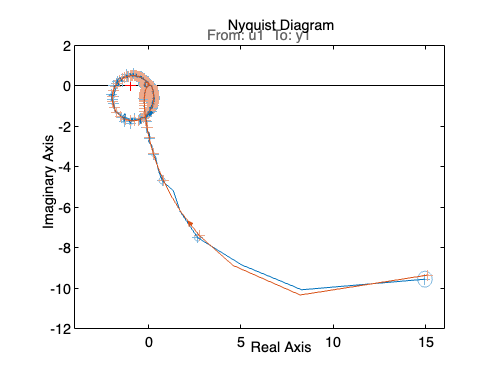

Gf_current = spa(data, 8191, freqs) ; 
G = stack( 1 , G_current ) ; 
Gf = stack( 1 , Gf_current ) ; 

figure(1)
nyquistplot ( Gf , G , freqs , opts , 'sd' , 2.45) ;

The uncertainties of the parametrical model have elliptical shape while the uncertainties of the stochastic model have circular shape. The fact that uncertainties are elliptical mean that the associated covariance matrix is not symmetrical. The uncertainties of the stochastic model are much more important than for the parametrical model.

5) Let's do the same thing on all the data

for idx = 2:length(files)
    disp(files{idx});
    load( files{idx} ) ; 
    G_current = oe(data , [8, 8, 1] ) ; 
    Gf_current = spa( data , 8191 , freqs ) ; 
    G = stack( 1 , G , G_current ) ; 
    Gf = stack( 1 , Gf , Gf_current ) ; 
end

Data/logs_3.mat
Data/logs_5.mat
Data/logs_7.mat
Data/logs_9.mat
Data/logs_11.mat


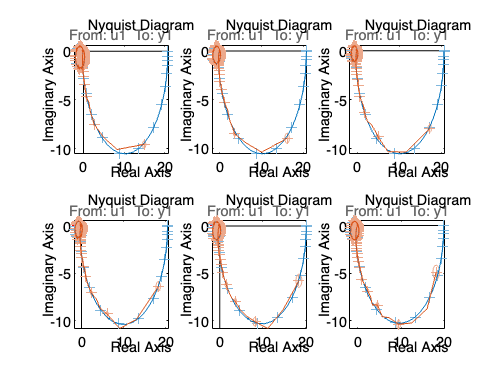


figure(2)

for i = 1:length(G)
    subplot( 2 , 3 , i )
    nyquistplot( G(:,:,i,:) , Gf(:,:,i,:) , opts , 'sd' , 2.45 ) ; 
end

5) We choose a weighing filter of order 4 as it gives satisfactory results.

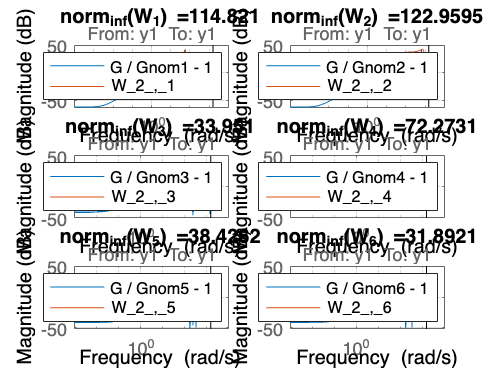

filter_order=4;
[~, info1] = ucover( G , G(:,:,1,:) , filter_order ) ;
W_current = info1.W1 ;
W_array=[W_current];
n_inf_current = norm( W_current , inf ) ; 
n_inf=[n_inf_current];

for i = 2:length(G)
    [~, info1] = ucover( G , G(:,:,i,:) , filter_order ) ;
    W_current = info1.W1 ;  
    n_inf_current = norm( info1.W1opt , inf ) ; 
    W_array = [W_array,W_current] ; 
    n_inf = [n_inf , n_inf_current] ;
end

figure(3)
for i = 1:length(W_array)
    nom_S = strcat( 'G / Gnom' , num2str( i ) , ' - 1' ) ;
    W_S = strcat( 'W_2_,_' , num2str( i ) ) ;
    subplot(3, 2, i)
    G_disp=G;
    G_disp(:,:,i,:)=[];
    bodemag( G_disp / G(:,:,i,:) - 1 , W_array(i) ) ; grid on ; legend( nom_S , strcat(W_S) ) ; 
    title( strcat( 'norm_{inf}(', W_S , ') = ', num2str( n_inf(i) ) ) )
end

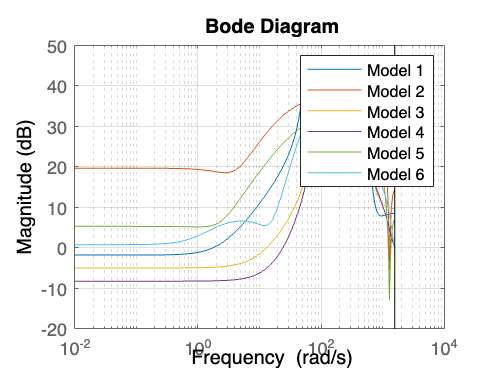


figure(4)
clf('reset')
legend_names = cell(1, numel(W_array));
for i = 1:length(W_array)
    bodemag(W_array(i)) ; 
    hold on;
    legend_names{i} = ['Model ', num2str(i)];
end
grid on;

legend(legend_names);

6) We choose the weighing filter with the lowest values at low frequencies. It means that we keep the model 7 as the nominal one which corresponds to our index four.

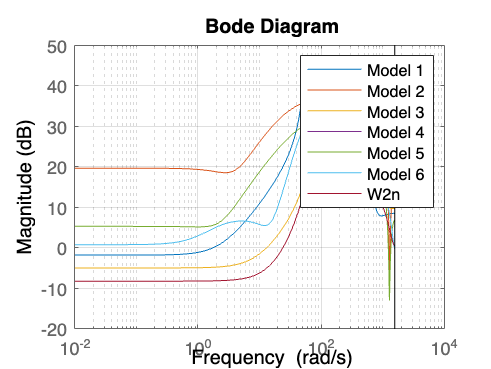

chosen_one = 4;

Gnom = G( : , : , chosen_one , : ) ;
W2n=W_array(chosen_one);

figure(5)
bodemag(W2n)

## 2.2  Model-based $H_{\infty }$ control design

1) We use the formula given in the course for continous time domain for the weighing filter $W_1$ and then convert it into the discrete time domain. $W_1(s)=m \frac{s + \omega_b}{s + 10^{-5}}$ with $m>0.5$ to respect the minimum bandwith condition and $\omega_b$ being empirically tuned to find a value that respect all criteria.

s=tf('s'); m=0.505; omega_b=2;
W1s=m*(s+omega_b)/(s+1e-5) ;
W1d=c2d(W1s,Ts,'tustin') ;

2)

[ K_inf_1 , CL , gamma ] = mixsyn( tf(Gnom) , W1d , [] , W2n ) ;
gamma

gamma = 0.5353

The infinite norm is bounded by $\gamma$ which is striclty lower than 1 thus ensuring robust stability.

3)

S_inf_1 = feedback( 1, G * K_inf_1 ) ;
T_inf_1 = feedback( G * K_inf_1 , 1 ) ;
U_inf_1 = feedback( K_inf_1 , G ) ;
    
% figure(6)
% step(S_inf_1) ;
% step(T_inf_1) ;
% step(U_inf_1) ;
% disp('fin')


4) As we don't know the input sensitivity function, we manually tweak the value of $W_3$ to make it comply with what is being wanted. A good first guess is : $W_3 =\frac{1}{1.5}$.

W3=1/1.5;

[K_inf_2,CL,gamma] = mixsyn( tf(Gnom) , W1d , W3 , W2n ) ;
gamma

gamma = 0.5450

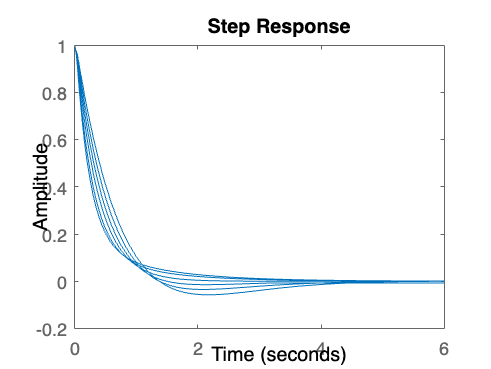

S_inf_2 = feedback( 1 , G * K_inf_2 ) ;
T_inf_2 = feedback( G * K_inf_2 , 1 ) ;
U_inf_2 = feedback( K_inf_2 , G ) ;
figure(7)
step(S_inf_2);

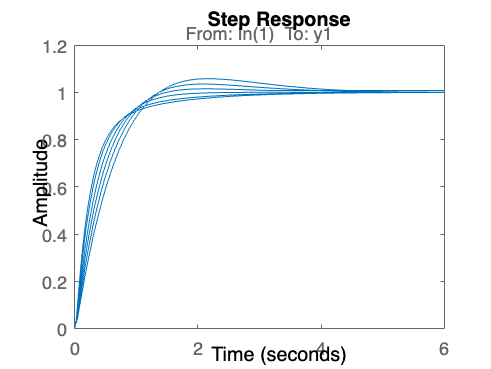

step(T_inf_2);

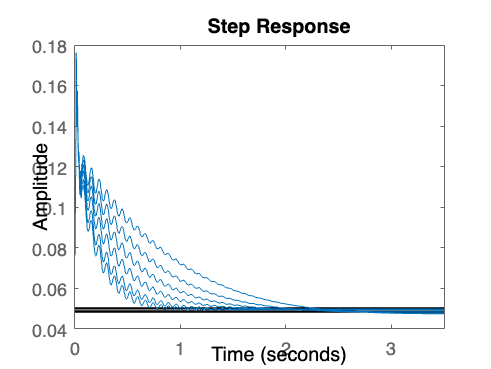

step(U_inf_2);

The infinite norm bound is strictly lower than 1 which ensures robust stability. The input has value in the prescribed domain.

5) Reducing controller order

# Comparer les performances des deux contrôleurs avec stepinfo : https://fr.mathworks.com/help/control/ref/dynamicsystem.stepinfo.html

order(K_inf_2)

ans = 33

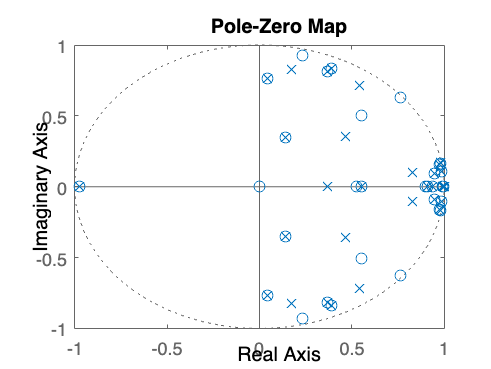

pzmap(K_inf_2);


% Little function to test if the system is stable
if isstable(T_inf_2)==1
    disp("The system is stable")
else
    disp("The system is unstable")
end

The system is stable


K_inf_r=minreal(K_inf_2);

20 states removed.


order(K_inf_r)

ans = 13

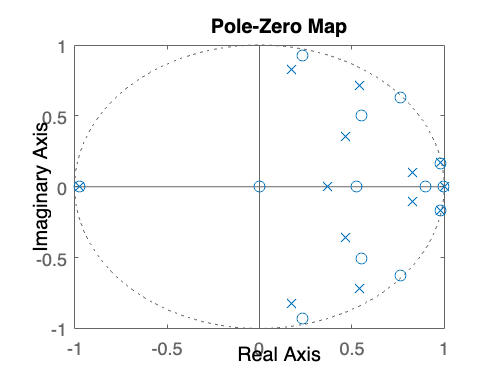

pzmap(K_inf_r)

S_inf_r = feedback( 1 , G * K_inf_r ) ;
T_inf_r = feedback( G * K_inf_r , 1 ) ;
U_inf_r = feedback( K_inf_r , G ) ;

%Stability test for closed-loop system
if isstable(T_inf_r)==1
    disp("The system is stable")
else
    disp("The system is unstable")
end

The system is stable



figure(8)
step(S_inf_r);

step(T_inf_r);

step(U_inf_r);

The difference are (finir la phrase)

6) We compute the infinite closed-loop norm of the first mixed sensitivity approach.

H_inf=[W1d*S_inf_1 ; W2n*T_inf_1];
norm(H_inf,inf)

ans =    11.0977
    7.6636
    3.8752
    0.5353
    4.1944
    7.3557


The 6 norms have an infinite norm strictly lower than 1 which ensures robust stability. The nominal model has the lowest infinite norm.

## 2.3 Model-based $H_2$ Controller design

1)

Gnom_c=d2c(Gnom);

[A,B,C,D]=ssdata(Gnom_c);
n=size(A,2);
m=size(B,2);

2) The state space equations take the following form :

#### 
$$\begin{cases}
      \dot x(t) = (A-BK)x(t) + Bv(t)\\
      z(t) = \left[\matrix{C \cr -K}\right]x(t)
    \end{cases}\,.$$


3) The optimization problem is given by :

#### 
$$\min_{K,L} \ tr\left( \left[\matrix{ C \cr -K}\right]L \left[\matrix{ C^T  -K^T}\right]  \right) = tr \left(CLC^T \right) + tr \left(KLK^T \right)$$


#### 
$$s.t. \ (A-BK)L +L(A-BK)^T+ BB^T \preceq 0 \ \text{and} \ L \succ 0$$


It is convex and the inequality constraint can be converted to an LMI setting $Y=KL$. However, the problem is not linear with respect to $K$and thus is not a semidefinite programming problem. To convert it, we define a square matrix $M \succ 0$ such that :

#### 
$$\begin{cases}
M \succeq KLK^T \\ L \succ 0\end{cases}
\iff 
\begin{cases}
M-YL^{-1}L^T \succeq 0 \\ L \succ 0
\end{cases}
\iff 
\left[ \matrix{
L & Y^T \cr Y & M
} \right] \succeq 0$$


We used Schur lemma to get the LMI. We did not use the one given in the course for definite matrix but the one for the semi-definite matrix that can be found at the following wikipedia page : [https://en.wikipedia.org/wiki/Schur_complement.](https://en.wikipedia.org/wiki/Schur_complement.) Finally, we get the semidefinite programming problem that can be solved with Mosek :

#### 
$$\min_{L,M,Y}  tr \left(CLC^T \right) + tr \left(M \right)$$


#### 
$$s.t. \ L\succ 0, \ AL - LA^T - BY - Y^TB^T + BB^T \preceq 0 \ \text{and} \ \left[ \matrix{
L & Y^T \cr Y & M
} \right] \succeq 0
$$


4)

L=sdpvar(n,n,'symmetric');
Y=sdpvar(m,n);
M=sdpvar(m,m);
lmi1=A*L + L*A' -B*Y - Y'*B' + B*B' <=0;
lmi2=[L Y';Y M] >=0;
lmi=[L>=0,lmi1,lmi2];
options=sdpsettings('solver','mosek');
optimize(lmi,trace(C*L*C')+trace(M),options);

MOSEK Version 10.1.28 (Build date: 2024-3-11 10:56:24)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 55              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 3 (scalarized: 145)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pri

L=value(L);
Y=value(Y);
M=value(M);
H2Norm=sqrt(trace(C*L*C')+trace(M))

H2Norm = 5.6568

K_H2=Y/L

K_H2 =     2.0000    0.4656    2.8658    1.2251    2.4430    1.7477    1.4860    2.6511    9.8458


5) Step response of the closed-loop system

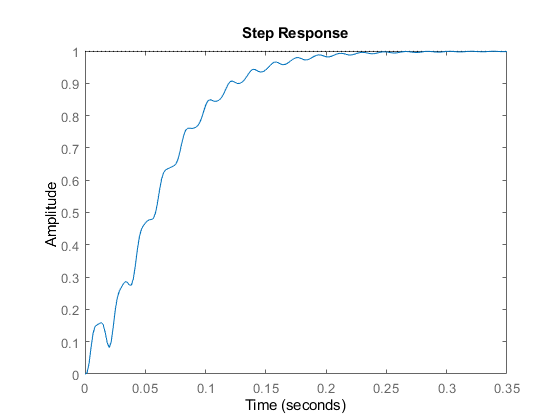

Gnom_closed=ss(A-B*K_H2,B,C,D);
figure(9)
step(Gnom_closed)

6)

Q=C'*C;
R=1;

K_lqr=lqr(A,B,Q,R)

K_lqr =     2.0000    0.4656    2.8658    1.2251    2.4430    1.7477    1.4860    2.6511    9.8458



diff=abs(norm(K_H2,2)-norm(K_lqr,2))

diff = 2.1864e-05

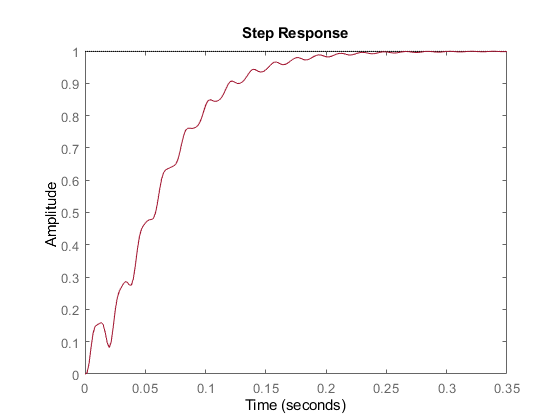


Gnom_closed_lqr=ss(A-B*K_lqr,B,C,D);

figure(10)
hold on
step(Gnom_closed_lqr)
step(Gnom_closed)
hold off

The absolute difference of the infinite norms is very little $2.2 {\times} 10^{-5}$, the two step responses are overlapping on the figure and if you compare the controllers element-wise, we can conclude that both problems give the same answer.

## 2.4 Data-driven controller

### 2.4.1 Multiplicative uncertainty

1) Stabilizing initial controller

z=tf("z");
c=0.0001;
Kc = c/(1-z^(-1))

Kc =
 
  0.0001 z
  --------
   z - 1
 
Sample time: unspecified
Discrete-time transfer function.



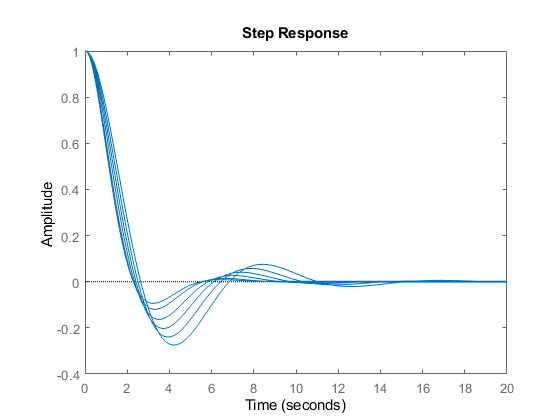


S = feedback( 1 , G * Kc ) ;
T = feedback( G * Kc , 1 ) ;
U = feedback( Kc , G ) ;
figure(11)
step(S);

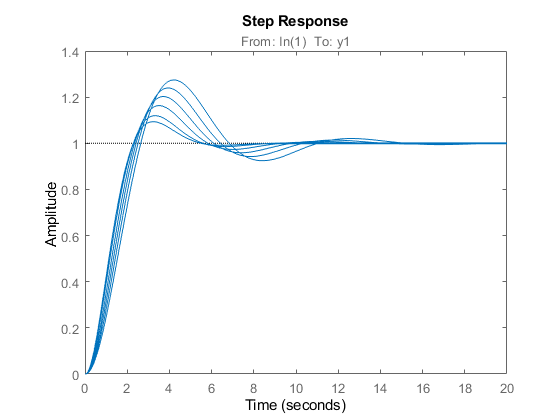

step(T);

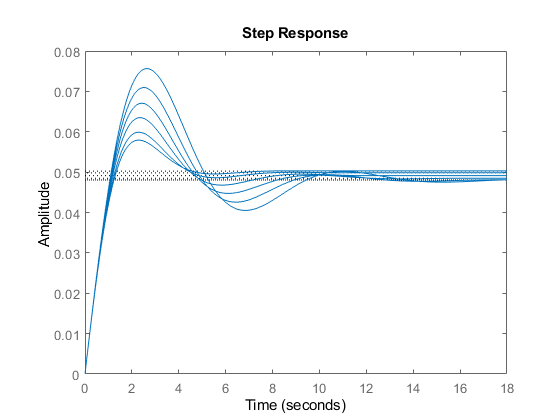

step(U);

2) We start by looking for a controller of order 15 which is the order of the reduced controller

% Load empty structure
[SYS, OBJ, CON, PAR] = datadriven.utils.emptyStruct();

% ------------------------------------------------------------------------------
%   Initial controller
% ------------------------------------------------------------------------------
                   % Initial controller
[num, den] = tfdata(Kc, 'v');   % Extract numerator and denominator
order_cont=15;

den(order_cont + 1) = 0; % Zero padding to have same order as desired controller
num(order_cont + 1) = 0; % Zero padding to have same order as desired controller

% Fixed parts of the controller
%   NOTE: Initial controller should contain the fixed parts too!
Fy = 1;                 % Fixed part of denominator as polynomial
den = deconv(den, Fy);  % Remove fixed part of denominator

Fx = 1;                 % Fixed part of numerator as polynomial
num = deconv(num, Fx);  % Remove fixed part of numerator

SYS.controller.num = num;
SYS.controller.den = den;
SYS.controller.Ts = Ts;
SYS.controller.Fx = Fx;
SYS.controller.Fy = Fy;

% ------------------------------------------------------------------------------
%   Nominal system(s)
% ------------------------------------------------------------------------------
% Systems should be LTI systems (`ss`, `tf`, `frd`, ...)
SYS.model = tf(Gnom)

SYS = struct with fields:
         model: [1×1 tf]
             W: []
    controller: [1×1 struct]



% ------------------------------------------------------------------------------
%   Frequencies for controller synthesis
% ------------------------------------------------------------------------------
SYS.W = logspace(-2,log10(pi/Ts),400);

% ------------------------------------------------------------------------------
%   Filters for objectives
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused objectives, set filters to []
OBJ.oinf.W1 = W1d;   % ║W1 S║∞
OBJ.oinf.W2 = tf(W2n);   % ║W2 T║∞
OBJ.oinf.W3 = tf(W3);   % ║W3 U║∞
OBJ.oinf.W4 = [];   % ║W4 V║∞

OBJ.o2.W1 = [];     % ║W1 S║₂
OBJ.o2.W2 = [];     % ║W2 T║₂
OBJ.o2.W3 = [];     % ║W3 U║₂
OBJ.o2.W4 = [];     % ║W4 V║₂

OBJ.LSinf.Ld = [];  % ║W (Ld - G K)║∞
OBJ.LSinf.W  = [];

OBJ.LS2.Ld = [];    % ║W (Ld - G K)║₂
OBJ.LS2.W  = [];

% ------------------------------------------------------------------------------
%   Filters for constraints
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused constraints, set filters to []
CON.W1 = W1d;    % ║W1 S║∞ ≤ 1
CON.W2 = tf(W2n);    % ║W2 T║∞ ≤ 1
CON.W3 = tf(W3);    % ║W3 U║∞ ≤ 1
CON.W4 = [];    % ║W4 V║∞ ≤ 1

% ------------------------------------------------------------------------------
%   Optimisation parameters
% ------------------------------------------------------------------------------
PAR.tol = 1e-4;     % Numerical tolerance for convergence
PAR.maxIter = 100;  % Maximum number of allowed iterations

verbosity = true;   % To print controller synthesis iterations
solver = "mosek";        % Solver to use for optimisation ("mosek", "sedumi", ...)

% ------------------------------------------------------------------------------
%   Solve the datadriven controller synthesis problem
% ------------------------------------------------------------------------------
[K_mu_max_order, sol] = datadriven.datadriven(SYS, OBJ, CON, PAR, verbosity, solver);

INFO: Solving for optimal controller in datadriven framework...
  |------|------------|------------|-------------|------------|
  | Iter |   Slack    |  Objective |   Decrease  | Solve Time |
  |------|------------|------------|-------------|------------|
  |  001 | 2.5193e-14 |            |             |       0.19 |
  |  002 |            | 4.2003e-01 |             |       2.06 |
  |  003 |            | 3.0460e-01 | -1.1543e-01 |       5.72 |
  |  004 |            | 3.0078e-01 | -3.8229e-03 |       7.43 |
  |  005 |            | 3.0050e-01 | -2.7256e-04 |       9.53 |
  |  006 |            | 3.0046e-01 | -4.6352e-05 |      10.33 |
  |------|------------|------------|-------------|------------|


order(K_mu_max_order)

ans = 15

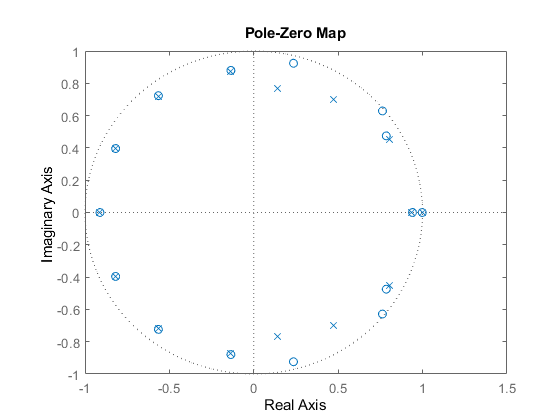

pzmap(K_mu_max_order);


S_mu_max_order  = feedback( 1 , G * K_mu_max_order ) ;
T_mu_max_order  = feedback( G * K_mu_max_order , 1 ) ;
U_mu_max_order  = feedback( K_mu_max_order , G ) ;

if isstable(T_mu_max_order)==1
    disp("The system is stable")
else
    disp("The system is unstable")
end

The system is stable


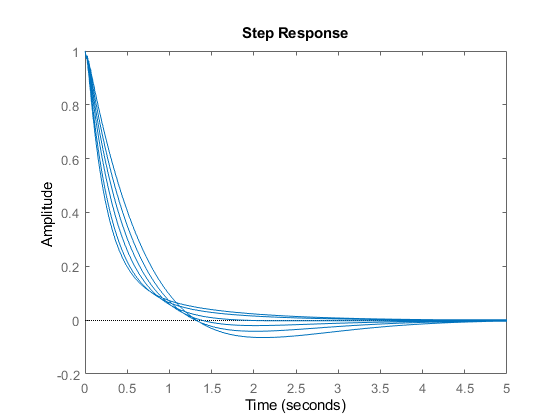



figure(12)
step(S_mu_max_order );

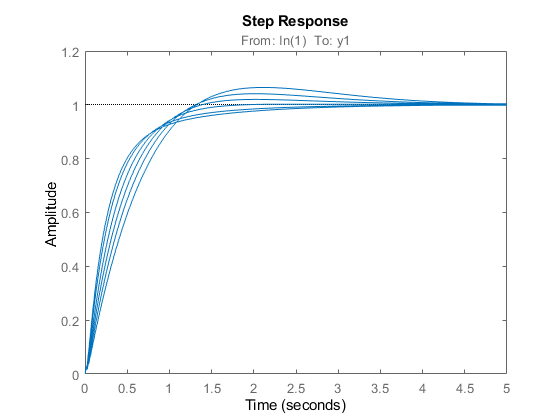

step(T_mu_max_order );

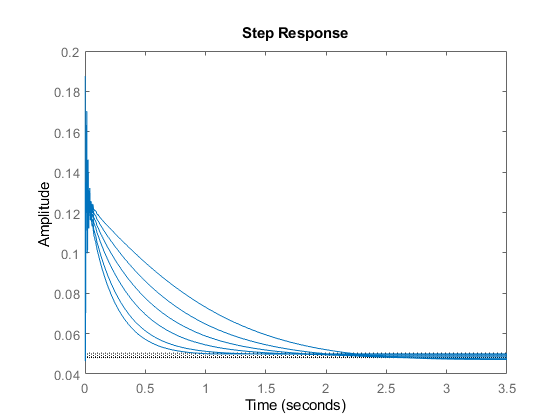

step(U_mu_max_order );

# Ajouter une partie avec la fonction stepinfo de matlab pour pouvoir comparer

3) For the reduced order controller, we use the function *minreal.*

K_mu_r_order=minreal(K_mu_max_order,0.001);
order(K_mu_r_order)

ans = 12

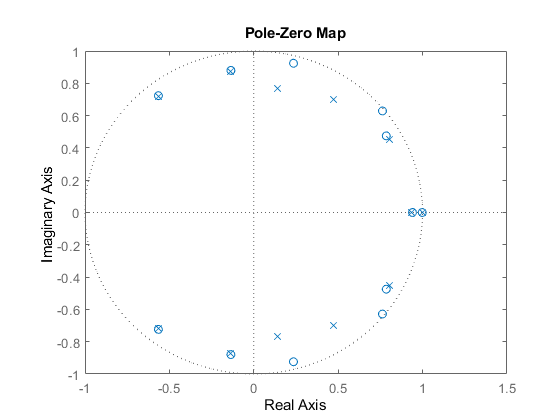

pzmap(K_mu_r_order)


S_mu_r_order = feedback( 1 , G * K_mu_r_order ) ;
T_mu_r_order = feedback( G * K_mu_r_order , 1 ) ;
U_mu_r_order = feedback( K_mu_r_order , G ) ;

if isstable(T_mu_r_order)==1
    disp("The system is stable")
else
    disp("The system is unstable")
end

The system is stable


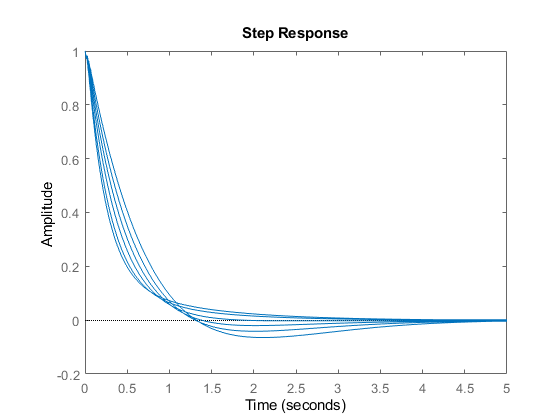


figure(13)
step(S_mu_r_order);

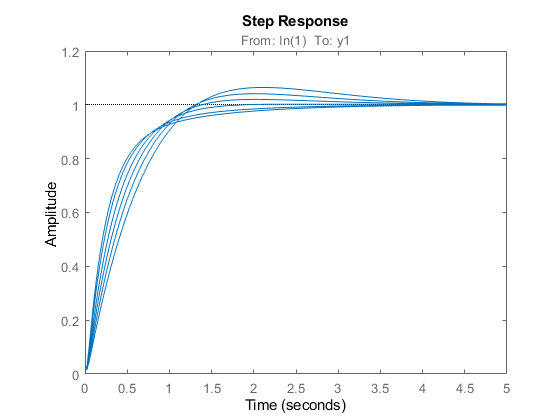

step(T_mu_r_order);

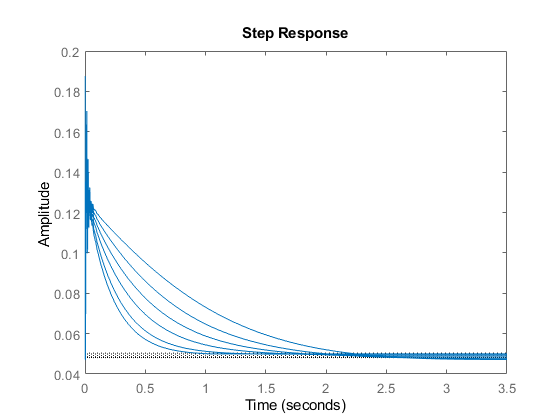

step(U_mu_r_order);

### 2.4.2 Multimodel uncertainty

1)

% Load empty structure
[SYS, OBJ, CON, PAR] = datadriven.utils.emptyStruct();

% ------------------------------------------------------------------------------
%   Initial controller
% ------------------------------------------------------------------------------
                   % Initial controller
[num, den] = tfdata(Kc, 'v');   % Extract numerator and denominator
order_cont=15;

den(order_cont + 1) = 0; % Zero padding to have same order as desired controller
num(order_cont + 1) = 0; % Zero padding to have same order as desired controller

% Fixed parts of the controller
%   NOTE: Initial controller should contain the fixed parts too!
Fy = 1;                 % Fixed part of denominator as polynomial
den = deconv(den, Fy);  % Remove fixed part of denominator

Fx = 1;                 % Fixed part of numerator as polynomial
num = deconv(num, Fx);  % Remove fixed part of numerator

SYS.controller.num = num;
SYS.controller.den = den;
SYS.controller.Ts = Ts;
SYS.controller.Fx = Fx;
SYS.controller.Fy = Fy;

% ------------------------------------------------------------------------------
%   Nominal system(s)
% ------------------------------------------------------------------------------
% Systems should be LTI systems (`ss`, `tf`, `frd`, ...)
SYS.model = tf(G)

SYS = struct with fields:
         model: [1×1×6×1 tf]
             W: []
    controller: [1×1 struct]



% ------------------------------------------------------------------------------
%   Frequencies for controller synthesis
% ------------------------------------------------------------------------------
SYS.W = logspace(-2,log10(pi/Ts),400);

% ------------------------------------------------------------------------------
%   Filters for objectives
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused objectives, set filters to []
OBJ.oinf.W1 = W1d;   % ║W1 S║∞
OBJ.oinf.W2 = tf(W2n);   % ║W2 T║∞
OBJ.oinf.W3 = tf(W3);   % ║W3 U║∞
OBJ.oinf.W4 = [];   % ║W4 V║∞

OBJ.o2.W1 = [];     % ║W1 S║₂
OBJ.o2.W2 = [];     % ║W2 T║₂
OBJ.o2.W3 = [];     % ║W3 U║₂
OBJ.o2.W4 = [];     % ║W4 V║₂

OBJ.LSinf.Ld = [];  % ║W (Ld - G K)║∞
OBJ.LSinf.W  = [];

OBJ.LS2.Ld = [];    % ║W (Ld - G K)║₂
OBJ.LS2.W  = [];

% ------------------------------------------------------------------------------
%   Filters for constraints
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused constraints, set filters to []
CON.W1 = W1d;    % ║W1 S║∞ ≤ 1
CON.W2 = tf(W2n);    % ║W2 T║∞ ≤ 1
CON.W3 = tf(W3);    % ║W3 U║∞ ≤ 1
CON.W4 = [];    % ║W4 V║∞ ≤ 1

% ------------------------------------------------------------------------------
%   Optimisation parameters
% ------------------------------------------------------------------------------
PAR.tol = 1e-4;     % Numerical tolerance for convergence
PAR.maxIter = 50;  % Maximum number of allowed iterations

verbosity = true;   % To print controller synthesis iterations
solver = "mosek";        % Solver to use for optimisation ("mosek", "sedumi", ...)

% ------------------------------------------------------------------------------
%   Solve the datadriven controller synthesis problem
% ------------------------------------------------------------------------------
[K_mm_max_order, sol] = datadriven.datadriven(SYS, OBJ, CON, PAR, verbosity, solver);

INFO: Solving for optimal controller in datadriven framework...
  |------|------------|------------|-------------|------------|
  | Iter |   Slack    |  Objective |   Decrease  | Solve Time |
  |------|------------|------------|-------------|------------|
  |  001 | 1.2722e-12 |            |             |       2.24 |
  |  002 |            | 6.7582e-01 |             |       5.50 |
  |  003 |            | 4.3317e-01 | -2.4265e-01 |       8.34 |
  |  004 |            | 4.0217e-01 | -3.1008e-02 |      12.50 |
  |  005 |            | 3.9223e-01 | -9.9331e-03 |      23.66 |
  |  006 |            | 3.8298e-01 | -9.2494e-03 |      26.39 |
  |  007 |            | 3.7569e-01 | -7.2886e-03 |      28.41 |
  |  008 |            | 3.7036e-01 | -5.3367e-03 |      31.50 |
  |  009 |            | 3.6670e-01 | -3.6578e-03 |      35.12 |
  |  010 |            | 3.6393e-01 | -2.7676e-03 |      47.82 |
  |  011 |            | 3.6203e-01 | -1.9015e-03 |      53.31 |
  |  012 |            | 3.6073e-01 | -1.

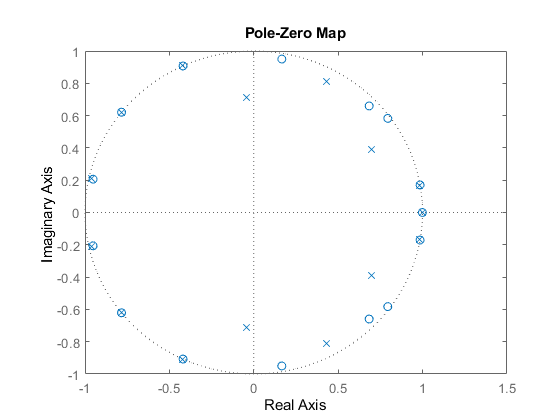

pzmap(K_mm_max_order);

order(K_mm_max_order)

ans = 15


S_mm_max_order = feedback( 1 , G * K_mm_max_order ) ;
T_mm_max_order = feedback( G * K_mm_max_order , 1 ) ;
U_mm_max_order = feedback( K_mm_max_order , G ) ;

if isstable(T_mm_max_order)==1
    disp("The system is stable")
else
    disp("The system is unstable")
end

The system is stable


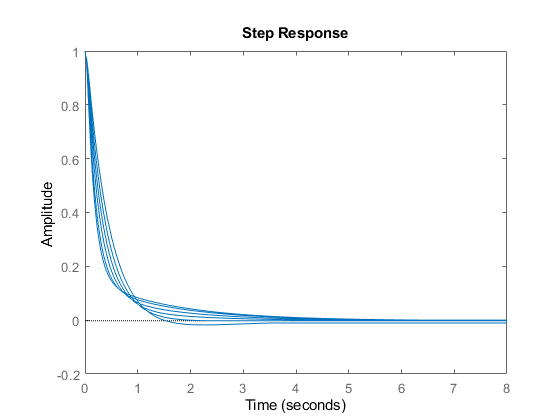


figure(14)
step(S_mm_max_order);

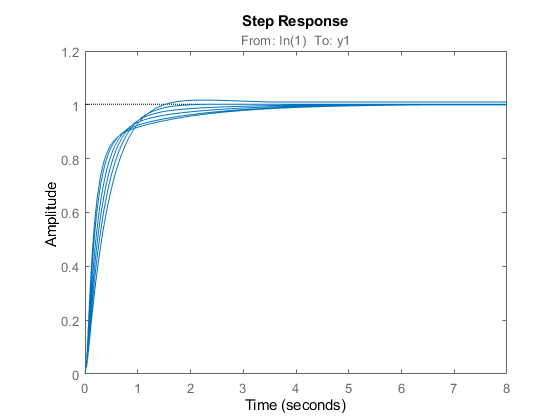

step(T_mm_max_order);

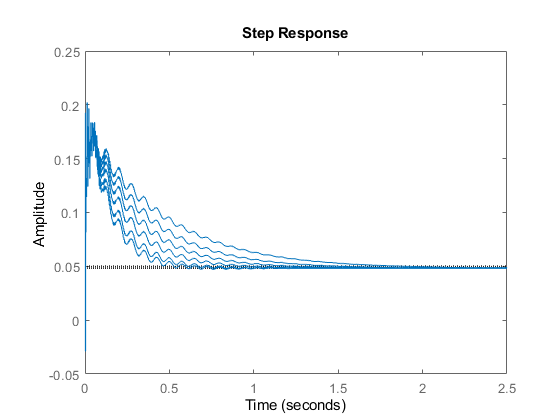

step(U_mm_max_order);

# Better performances + add comparison

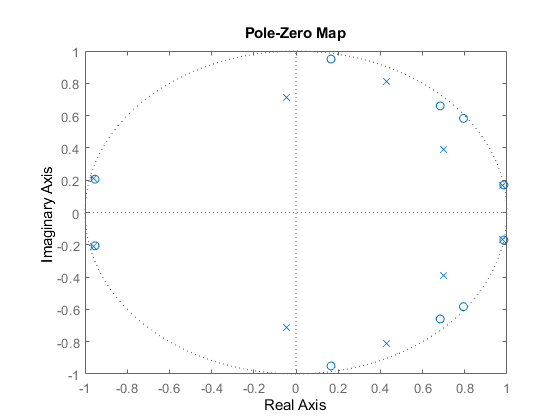

K_mm_r_order=minreal(K_mm_max_order,0.001);

order(K_mm_r_order)

ans = 10

pzmap(K_mm_r_order);

S_mm_r_order = feedback( 1 , G * K_mm_r_order ) ;
T_mm_r_order = feedback( G * K_mm_r_order , 1 ) ;
U_mm_r_order = feedback( K_mm_r_order , G ) ;

if isstable(T_mm_r_order)==1
    disp("The system is stable")
else
    disp("The system is unstable")
end

The system is stable


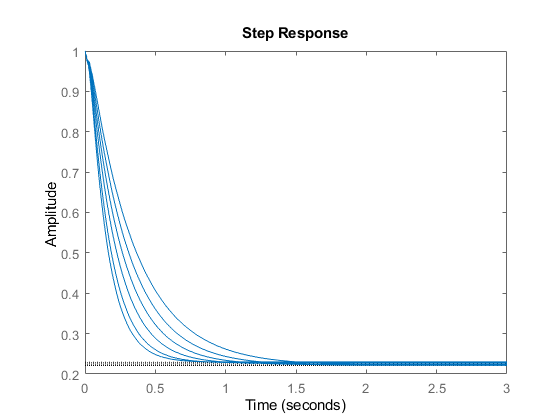


figure(15)
step(S_mm_r_order);

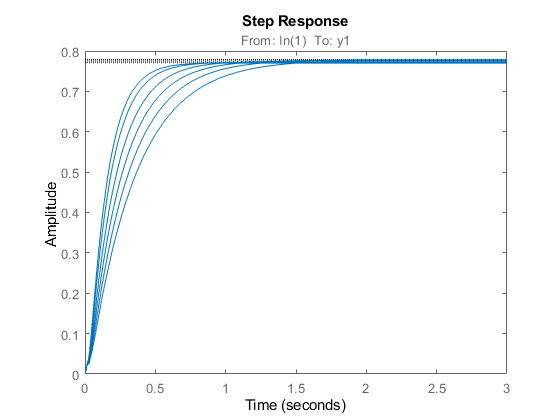

step(T_mm_r_order);

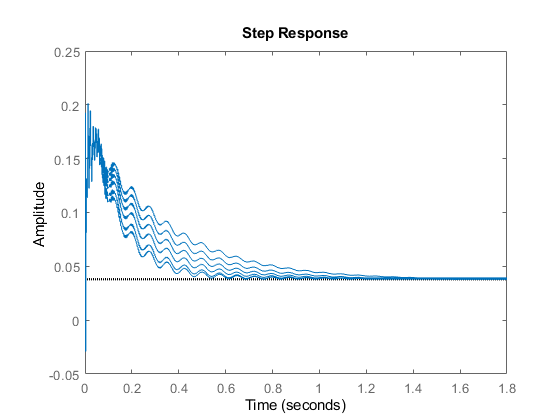

step(U_mm_r_order);

Comparison data-driven approach - model-based approach. Data-driven is quite long to compute but it can give really good controllers with much lower orders.

# Peaufiner conclusion